# Manipolatore Stanford: Disaccoppiamento Polso - Struttura Portante

Il **disaccoppiamento **permette di separare il problema in parti piu semplici:

- **Cinematica Posizione: **Trovare i valori dei primi tre giunti $(q_1 ,q_2 ,q_3 )$ che posizionano il centro del polso nel punto desiderato

- **Cinematica Orientamento: **Trovare i valori degli ultimi tre giunti $(q_4 ,q_5 ,q_6 )$ per ottenere l'orientamento desiderato dell'end effector avendo già posizionato il polso

Si definiscono tutte le variabili simboliche che includono le variabili di giunto $(q_1 ,\ldots,q_6 )$ e i parametri geometrici costanti del manipolatore, come le lunghezze dei link $d_2$ e $d_6$

% Risoluzione percorso cartella funzioni ausiliarie Codici Matlab
if ~exist('Compute_DH_Transformations', 'file') || ~exist('Compute_Rotation_Matrix', 'file')
    candDirs = {pwd, fileparts(pwd)};
    try
        edFile = matlab.desktop.editor.getActiveFilename;
        candDirs = [candDirs, {fileparts(edFile), fileparts(fileparts(edFile))}];
    catch
    end
    for iCand = 1:numel(candDirs)
        cDir = candDirs{iCand};
        if isfolder(cDir) && (isfile(fullfile(cDir, 'Compute_DH_Transformations.m')) || isfile(fullfile(cDir, 'Compute_Rotation_Matrix.m')))
            addpath(cDir);
            break;
        end
    end
end
clc; clear; close all;
% Variabili Simboliche Struttura
syms q1 q2 q3 d2 real;
% Variabili Simboliche Polso
syms q4 q5 q6 d6 real;

Si definiscono i parametri di Denavit-Hartenberg per la struttura portante (**Giunti 1 - 3**) e per il polso (**Giunti 4 - 6**) che descrivono la relazione cinematica tra i link consecutivi.

% Definizione Tabelle DH Struttura
DH_Table_Strut = [q1, 0, -pi/2, 0;
                  q2, d2, pi/2, 0;
                  0, q3, 0, 0];

% Definizione Tabelle DH Polso
DH_Table_Polso = [q4, 0, -pi/2, 0;
                  q5, 0, pi/2, 0;
                  q6, d6, 0, 0];

Utilizzando i parametri DH, si calcolano le **matrici di trasformazione omogenea** per ogni link tramite la funzione `Compute_DH_Transformations.`

% Calcolo Matrici Trasformazione E Rotazione Struttura
[T_Mat_Strut, R_Mat_Strut] = Compute_DH_Transformations(DH_Table_Strut);

% Calcolo Matrici Trasformazione E Rotazione Polso
[T_Mat_Polso, R_Mat_Polso] = Compute_DH_Transformations(DH_Table_Polso);

A questo punto si possono comporre le matrici individuali per ottenere le trasformazioni totali:

- `T03`: Dalla base al centro del polso .

- `T36`: dal centro del polso all'end-effector

fprintf('Matrice di trasformazione omogenea ^{%d}T_(%d):', 0, 3);

Matrice di trasformazione omogenea ^{0}T_(3):

T03 = simplify(T_Mat_Strut(:,:,1) * T_Mat_Strut(:,:,2) * T_Mat_Strut(:,:,3));
disp(T03);

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

fprintf('Matrice di trasformazione omogenea ^{%d}T_(%d):', 3, 6);

Matrice di trasformazione omogenea ^{3}T_(6):

T36 = simplify(T_Mat_Polso(:,:,1) * T_Mat_Polso(:,:,2) * T_Mat_Polso(:,:,3));
disp(T36);

$$\left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{5}\right) & d_{6}\,\cos\left(q_{5}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$\begin{pmatrix} c\left(q_4 \right)\,c\left(q_5 \right)\,c\left(q_6 \right)-s\left(q_4 \right)\,s\left(q_6 \right) & -c\left(q_6 \right)\,s\left(q_4 \right)-c\left(q_4 \right)\,c\left(q_5 \right)\,s\left(q_6 \right) & c\left(q_4 \right)\,s\left(q_5 \right) & d_6 \,c\left(q_4 \right)\,s\left(q_5 \right)\\ c\left(q_4 \right)\,s\left(q_6 \right)+c\left(q_5 \right)\,c\left(q_6 \right)\,s\left(q_4 \right) & c\left(q_4 \right)\,c\left(q_6 \right)-c\left(q_5 \right)\,s\left(q_4 \right)\,s\left(q_6 \right) & s\left(q_4 \right)\,s\left(q_5 \right) & d_6 \,s\left(q_4 \right)\,s\left(q_5 \right)\\ -c\left(q_6 \right)\,s\left(q_5 \right) & s\left(q_5 \right)\,s\left(q_6 \right) & c\left(q_5 \right) & d_6 \,c\left(q_5 \right)\\ 0 & 0 & 0 & 1 \end{pmatrix}$$


La terna 3 del **manipolatore sferico** coincide con la terna 3 del **polso sferico**, la funzione cinematica diretta può essere ottenuta semplicemente per composizione delle matrici di trasformazione come${\,}^0 T_6 ={\,}^0 T_3 \cdot {\,}^3 T_6$

T06 = simplify(T03 * T36);
% fprintf('Matrice di trasformazione omogenea ^{%d}T_(%d):', 0, 6);
% disp(T06);

Il vettore $d_{36}$ rappresenta il **vettore di traslazione** che descrive la posizione dell'origine del sistema di riferimento dell'end-effector rispetto all'origine del sistema di riferimento del polso.\ In pratica, è il \underline{vettore di posizione dell'end-effector visto dal centro del polso}.

d36 = T36(1:3, 4);
fprintf('Vettore d_{36}');

Vettore d_{36}

disp(d36);

$$\left(\begin{array}{c} d_{6}\,\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ d_{6}\,\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ d_{6}\,\cos\left(q_{5}\right) \end{array}\right)$$

## Cinematica Inversa Posizione

Si deve verificare che il vettore che collega il centro del polso all'end-effector, quando espresso nelle coordinate dell'end-effector (terna 6), sia costante. Questo vettore `d1` si calcola come:


$$\exists \;d_0 ,\,d_1 \in {\mathbb{R}}^3 \;\mid \;d_{36} =^3 R_6 d_1 +d_0$$


Dato che $d_{36}$ non presenta termini indipendenti dalle variabili di giunto, questo ci dice che non c'è un offset fisso dal polso, e quindi non c'è uno spostamento strutturale fisso, visto dal polso e di conseguenza allora $d_0 =0$


$$d_{36} = {}^{3}R_{6} \; d_{1} \qquad \longrightarrow \qquad d_{1} = \bigl({}^{3}R_{6}\bigr)^{T} d_{36}$$


Poichè $^3 R_6$ è una matrice di rotazione, si ha che ${\bigl(^3 R_6 \bigr)}^{-1} ={\bigl(^3 R_6 \bigr)}^T$

R36 = simplify(R_Mat_Polso(:,:,1) * R_Mat_Polso(:,:,2) * R_Mat_Polso(:,:,3));
R36_T = R36';
d1 = simplify(R36_T * d36);
fprintf('Vettore d_{1}');

Vettore d_{1}

disp(d1);

$$\left(\begin{array}{c} 0\\ 0\\ d_{6} \end{array}\right)$$

Questo è il vettore che collega il centro del polso (origine di $RF_3$) all'end-effector (origine di $RF_6$), espresso in coordinate del sistema $RF_6$.

Sapendo che la posizione desiderata dell'end-effector è $d_{06}$, si può scrivere


$$d_{06} =d_{03} +^0 R_6 \;d_1$$


Cioè, il vettore che va dalla **base all'end effector** è uguale al vettore che va dalla **base al polso** più il vettore che va dal **polso all'end effector. **Quindi, dalla precedente si può dire che la posizione del centro del polso $d_{03}$ può essere calcolata come $d_{03} =d_{06} -^0 R_6 \;d_1$, dove $d_{06}$ è il vettore obiettivo cioè la posizione finale che deve avere l'end effector

syms dx dy dz real;

% Posa Desiderata (INPUT DEL PROBLEMA)
d06 = [dx; dy; dz];

% Orientamento Desiderato Tramite Matrice Di Rotazione (INPUT DEL PROBLEMA)
R06_End = sym('R', [3, 3], 'real');

fprintf('Posizione Desiderata (d06):');

Posizione Desiderata (d06):

disp(d06);

$$\left(\begin{array}{c} \mathrm{dx}\\ \mathrm{dy}\\ \mathrm{dz} \end{array}\right)$$

fprintf('Orientamento Desiderato (R06_End):');

Orientamento Desiderato (R06_End):

disp(R06_End);

$$\left(\begin{array}{ccc} R_{1,1} & R_{1,2} & R_{1,3}\\ R_{2,1} & R_{2,2} & R_{2,3}\\ R_{3,1} & R_{3,2} & R_{3,3} \end{array}\right)$$

d03 = T03(1:3, 4);
fprintf('Posizione Calcolata Struttura Portante (d03):');

Posizione Calcolata Struttura Portante (d03):

disp(d03);

$$\left(\begin{array}{c} q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)\\ d_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

## Valore $q_3$

Si indica con $d_{hat}$ il vettore che rappresenta la posizione desiderata del centro del polso rispetto al sistema di riferimento di base. Questo si può calcolare come:


$$\hat{d} =d_{06} -^0 R_6 \cdot d_1$$


Questo vettore d_{hat} è considerato **noto**, in quanto $d_{06}$ (la posizione finale) e $^0 R_6$ (l'orientamento finale) sono **gli input problema** di cinematica inversa.

% Box di Calcolo d_hat
% d_hat = d06_des - R06_des * d1_vec

% Calcolo posizione target del polso
d_hat = d06 - R06_End * d1;
fprintf('Posizione Desiderata Struttura Portante (d_hat):');

Posizione Desiderata Struttura Portante (d_hat):

disp(d_hat);

$$\left(\begin{array}{c} \mathrm{dx}-R_{1,3}\,d_{6}\\ \mathrm{dy}-R_{2,3}\,d_{6}\\ \mathrm{dz}-R_{3,3}\,d_{6} \end{array}\right)$$

% Avendo come input un vettore e un orientamento numerici, questo sara un vettore numerico

A questo punto si hanno due rappresentazioni della posizione del centro del polso:

- $\hat{d}$: che è un vettore noto in quanto calcolato tramite gli **input del problema**

- $d_{03}$: che è il vettore di posizione calcolato dalla cinematica diretta e dipende da $q1,q2,q3$

L'end-effector deve poter raggiungere la posa, quindi una condizione necessaria è che la lunghezza (o norma) del vettore target $\hat{d}$ sia uguale alla lunghezza del vettore $d_{03}$. Quindi, uguagliando le loro norme al quadrato, si ottiene:

norm_sq_d_hat = norm(d_hat)^2;
norm_sq_d03 = norm(d03)^2;

norm_sq_d_hat = simplify(norm_sq_d_hat);
norm_sq_d03 = simplify(norm_sq_d03);

fprintf('Norma del vettore target (d_hat):');

Norma del vettore target (d_hat):


disp(norm_sq_d_hat);

$${\left(\mathrm{dx}-R_{1,3}\,d_{6}\right)}^{2}+{\left(\mathrm{dy}-R_{2,3}\,d_{6}\right)}^{2}+{\left(\mathrm{dz}-R_{3,3}\,d_{6}\right)}^{2}$$

Come detto prima $\hat{d}$ è un vettore noto, la sua norma al quadrato sarà un valore numerico. Poichè si stanno eseguendo i calcoli in maniera simbolica, per evitare risultati simbolici troppo lunghi e complessi chiamo questo valore `dHatNormSq`

syms dHatNormSq real;

fprintf('Norma al quadrato del vettore calcolato (d_03):');

Norma al quadrato del vettore calcolato (d_03):


disp(norm_sq_d03);

$${d_{2}}^{2}+{q_{3}}^{2}$$

eq_q3 = (dHatNormSq == norm_sq_d03);

fprintf('Equazione per trovare q3:');

Equazione per trovare q3:

disp(eq_q3);

$$\mathrm{dHatNormSq}={d_{2}}^{2}+{q_{3}}^{2}$$

% Risolviamo per q3
sol_q3 = solve(eq_q3, q3, ReturnConditions=true);
q3_pos = sol_q3.q3(1);
q3_neg = sol_q3.q3(2);

fprintf('Soluzioni per q3:');

Soluzioni per q3:

fprintf('q3_1 = ');

q3_1 = 

disp(q3_pos);

$$\sqrt{\mathrm{dHatNormSq}-{d_{2}}^{2}}$$

fprintf('q3_2 =');

q3_2 =

disp(q3_neg);

$$-\sqrt{\mathrm{dHatNormSq}-{d_{2}}^{2}}$$

fprintf('Entrambe le soluzioni sono valide se:');

Entrambe le soluzioni sono valide se:

disp(sol_q3.conditions(2));

$${d_{2}}^{2}\leq \mathrm{dHatNormSq}$$

Queste due soluzioni corrispondono a due diverse configurazioni del braccio:

- **Gomito Alto** (Soluzione Positiva): Il gomito è sopra la linea che collega la base all'end-effector

- **Gomito Basso** (Soluzione Negativa): Il gomito è sotto la linea che collega la base all'end-effector

Ugualiando $\hat{d}$ (**Vettore posizione target polso**) e $d_{03}$ (**Vettore posizione polso cinematica diretta**) si ottiene il sistema

fprintf('Sistema da risolvere per trovare q1 e q2');

Sistema da risolvere per trovare q1 e q2

eq_system = d03 == d_hat;
disp(eq_system);

$$\left(\begin{array}{c} q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)=\mathrm{dx}-R_{1,3}\,d_{6}\\ d_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)=\mathrm{dy}-R_{2,3}\,d_{6}\\ q_{3}\,\cos\left(q_{2}\right)=\mathrm{dz}-R_{3,3}\,d_{6} \end{array}\right)$$

## Valore $q_2$

Si nota che, dalla terza equazione si può trovare $\cos (q_2 )$

syms c2 real;
eq_cosq2 = eq_system(3);
fprintf('Terza Equazione:');

Terza Equazione:

disp(eq_cosq2);

$$q_{3}\,\cos\left(q_{2}\right)=\mathrm{dz}-R_{3,3}\,d_{6}$$

cosq2_eq = isolate(eq_cosq2, cos(q2));
fprintf('Equazione cos(q2):');

Equazione cos(q2):

disp(cosq2_eq);

$$\cos\left(q_{2}\right)=\frac{\mathrm{dz}-R_{3,3}\,d_{6}}{q_{3}}$$

Poiché $\sin^2 (q_2 )+\cos^2 (q_2 )=1$, si hanno due possibili soluzioni per $\sin (q_2 )$:


$$\sin (q_2 )=\pm \sqrt{1-\cos (q_2 )^2 \;\;}$$


cosq2 = rhs(cosq2_eq);

sinq2_pos = sqrt(1 - cosq2^2);
sinq2_neg = -sqrt(1 - cosq2^2);

q2_neg = atan2(sinq2_neg, cosq2);
q2_pos = atan2(sinq2_pos, cosq2);

fprintf('Valore q2 Per Valore Seno Negativo:');

Valore q2 Per Valore Seno Negativo:


disp(q2_neg);

$$\text{atan2}\left(-\sqrt{1-\frac{{\left(\mathrm{dz}-R_{3,3}\,d_{6}\right)}^{2}}{{q_{3}}^{2}}},\frac{\mathrm{dz}-R_{3,3}\,d_{6}}{q_{3}}\right)$$

fprintf('Valore q2 Per Valore Seno Positivo:');

Valore q2 Per Valore Seno Positivo:

disp(q2_pos);

$$\text{atan2}\left(\sqrt{1-\frac{{\left(\mathrm{dz}-R_{3,3}\,d_{6}\right)}^{2}}{{q_{3}}^{2}}},\frac{\mathrm{dz}-R_{3,3}\,d_{6}}{q_{3}}\right)$$

## Valore $q_1$

Si nota che, la prima e la seconda equazione del precedente sistema formano un sistema utile per trovare$\cos (q_1 )$

syms c1 s1 real;
eq_q1 = eq_system(1:2);
disp(eq_q1);

$$\left(\begin{array}{c} q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-d_{2}\,\sin\left(q_{1}\right)=\mathrm{dx}-R_{1,3}\,d_{6}\\ d_{2}\,\cos\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)=\mathrm{dy}-R_{2,3}\,d_{6} \end{array}\right)$$

eq_q1_sym = subs(eq_q1, [cos(q1), sin(q1)], [c1, s1]);

sol_q1 = solve(eq_q1_sym, [c1, s1]);
sinq1 = simplify(sol_q1.s1);
cosq1 = simplify(sol_q1.c1);

fprintf('Soluzioni Del Sistema:');

Soluzioni Del Sistema:


disp(sin(q1) == sinq1);

$$\sin\left(q_{1}\right)=-\frac{d_{2}\,\mathrm{dx}-\mathrm{dy}\,q_{3}\,\sin\left(q_{2}\right)-R_{1,3}\,d_{2}\,d_{6}+R_{2,3}\,d_{6}\,q_{3}\,\sin\left(q_{2}\right)}{{d_{2}}^{2}+{q_{3}}^{2}\,{\sin\left(q_{2}\right)}^{2}}$$


disp(cos(q1) == cosq1);

$$\cos\left(q_{1}\right)=\frac{d_{2}\,\mathrm{dy}+\mathrm{dx}\,q_{3}\,\sin\left(q_{2}\right)-R_{2,3}\,d_{2}\,d_{6}-R_{1,3}\,d_{6}\,q_{3}\,\sin\left(q_{2}\right)}{{d_{2}}^{2}+{q_{3}}^{2}\,{\sin\left(q_{2}\right)}^{2}}$$

A questo punto, usando la funzione arcotangente a quattro quadranti si può calcolare il valore di $q_1$

q1_val = atan2(sinq1, cosq1);

fprintf('Valore q1:');

Valore q1:

disp(q1_val);

$$\text{atan2}\left(-\frac{d_{2}\,\mathrm{dx}-\mathrm{dy}\,q_{3}\,\sin\left(q_{2}\right)-R_{1,3}\,d_{2}\,d_{6}+R_{2,3}\,d_{6}\,q_{3}\,\sin\left(q_{2}\right)}{{d_{2}}^{2}+{q_{3}}^{2}\,{\sin\left(q_{2}\right)}^{2}},\frac{d_{2}\,\mathrm{dy}+\mathrm{dx}\,q_{3}\,\sin\left(q_{2}\right)-R_{2,3}\,d_{2}\,d_{6}-R_{1,3}\,d_{6}\,q_{3}\,\sin\left(q_{2}\right)}{{d_{2}}^{2}+{q_{3}}^{2}\,{\sin\left(q_{2}\right)}^{2}}\right)$$

## Cinematica Inversa Orientamento

Una volta determinati $q_1 ,q_2 ,q_3$, la matrice di rotazione $^0 R_3$ è nota, quindi si può o calcolare la matrice di rotazione del polso $^3 R_6$richiesta per raggiungere l'orientamento finale $^0 R_6$ dato che:


$$^0 R_6 =^0 R_3 \cdot ^3 R_6$$


Sapendo che le matrici di rotazioni sono invertibili e l'inversa di una matrice di rotazione è uguale alla trasposta si ha che la matrice "target" per ottenere l'orientamento desiderato è


$$^3 R_6 ={\bigl(^0 R_3 \bigr)}^{-1} \;^0 R_6 ={\bigl(^0 R_3 \bigr)}^T \;^0 R_6$$


Dove

- $^0 R_6$: Rappresenta la matrice di rotazione desiderata per l'end-effector, che è un dato di input del problema di cinematica inversa.

- ${\bigl(^0 R_3 \bigr)}^T$ Dipende da $q_1 ,q_2 ,q_3$ che sono appena stati calcolati. Sostituendo i loro valori numerici nella matrice di rotazione della struttura portante (estratta dalla matrice $^0 T_3$ ), otteniamo una matrice numerica conosciuta.

- $^3 R_6$: Dipende dagli angoli $q_4 ,q_5 ,q_6$ che si devono trovare.

**Poichè si stanno facendo dei calcoli simbolici, indichiamo con **`R03_K`** (Known) la matrice che contiene i valori numerici calcolati (*****termini noti***) e con `R36_T`** (Target) la matrice di rotazione estratta dalla matrice di trasformazione omogenea **$^3 T_6$** ottenuta tramite le tabelle di Denavit-Hartenberg che dipende da **$q_4 ,q_5 ,q_6$** (*****incognite***)

% Valori noti a questo punto "_K"
% Valori da calcolare "_T"
% Orientamento Finale R06_K = R03_K * R36_T

% Matrice Rotazione R06 Nota (Input Problema)
R06_K = sym('R06K', [3, 3], 'real');
fprintf('Matrice Rotazione R06 Nota:');

Matrice Rotazione R06 Nota:


disp(R06_K);

$$\left(\begin{array}{ccc} {\mathrm{R06K}}_{1,1} & {\mathrm{R06K}}_{1,2} & {\mathrm{R06K}}_{1,3}\\ {\mathrm{R06K}}_{2,1} & {\mathrm{R06K}}_{2,2} & {\mathrm{R06K}}_{2,3}\\ {\mathrm{R06K}}_{3,1} & {\mathrm{R06K}}_{3,2} & {\mathrm{R06K}}_{3,3} \end{array}\right)$$

% Matrice Rotazione R03 Nota (Calcolata Con q1, q2, q3)
R03_K = sym('R03K', [3, 3], 'real');
fprintf('Matrice Rotazione R03 Nota:');

Matrice Rotazione R03 Nota:


disp(R03_K);

$$\left(\begin{array}{ccc} {\mathrm{R03K}}_{1,1} & {\mathrm{R03K}}_{1,2} & {\mathrm{R03K}}_{1,3}\\ {\mathrm{R03K}}_{2,1} & {\mathrm{R03K}}_{2,2} & {\mathrm{R03K}}_{2,3}\\ {\mathrm{R03K}}_{3,1} & {\mathrm{R03K}}_{3,2} & {\mathrm{R03K}}_{3,3} \end{array}\right)$$

% Matrice Rotazione R36 Con Incognite
R36_T = simplify(R_Mat_Polso(:,:,1) * R_Mat_Polso(:,:,2) * R_Mat_Polso(:,:,3));
fprintf('Matrice Rotazione R36 Incognite:');

Matrice Rotazione R36 Incognite:

disp(R36_T);

$$\left(\begin{array}{ccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)\\ -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{5}\right) \end{array}\right)$$

Con la formula $^3 R_6 ={\bigl(^0 R_3 \bigr)}^T \;^0 R_6$ si può calcolare la matrice $^3 R_6$ nota (`R36_K`) e poi confrontandola membro a membro con $^3 R_6$ incognita si ottiene un sistema con incognite ($q_4 ,q_5 ,q_6$)

R03_K_Trasp = R03_K';

R36_Calc = R03_K_Trasp * R06_K;
fprintf('Matrice Rotazione R36 Nota Calcolata:');

Matrice Rotazione R36 Nota Calcolata:

disp(R36_Calc);

$$\left(\begin{array}{ccc} {\mathrm{R03K}}_{1,1}\,{\mathrm{R06K}}_{1,1}+{\mathrm{R03K}}_{2,1}\,{\mathrm{R06K}}_{2,1}+{\mathrm{R03K}}_{3,1}\,{\mathrm{R06K}}_{3,1} & {\mathrm{R03K}}_{1,1}\,{\mathrm{R06K}}_{1,2}+{\mathrm{R03K}}_{2,1}\,{\mathrm{R06K}}_{2,2}+{\mathrm{R03K}}_{3,1}\,{\mathrm{R06K}}_{3,2} & {\mathrm{R03K}}_{1,1}\,{\mathrm{R06K}}_{1,3}+{\mathrm{R03K}}_{2,1}\,{\mathrm{R06K}}_{2,3}+{\mathrm{R03K}}_{3,1}\,{\mathrm{R06K}}_{3,3}\\ {\mathrm{R03K}}_{1,2}\,{\mathrm{R06K}}_{1,1}+{\mathrm{R03K}}_{2,2}\,{\mathrm{R06K}}_{2,1}+{\mathrm{R03K}}_{3,2}\,{\mathrm{R06K}}_{3,1} & {\mathrm{R03K}}_{1,2}\,{\mathrm{R06K}}_{1,2}+{\mathrm{R03K}}_{2,2}\,{\mathrm{R06K}}_{2,2}+{\mathrm{R03K}}_{3,2}\,{\mathrm{R06K}}_{3,2} & {\mathrm{R03K}}_{1,2}\,{\mathrm{R06K}}_{1,3}+{\mathrm{R03K}}_{2,2}\,{\mathrm{R06K}}_{2,3}+{\mathrm{R03K}}_{3,2}\,{\mathrm{R06K}}_{3,3}\\ {\mathrm{R03K}}_{1,3}\,{\mathrm{R06K}}_{1,1}+{\mathrm{R03K}}_{2,3}\,{\mathrm{R06K}}_{2,1}+{\mathrm{R03K}}_{3,3}\,{\mathrm{R06K}}_{3,1} & {\mathrm{R03K}}_{1,3}\,{\mathrm{R06K}}_{1,2}+{\mathrm{R03K}}_{2,3}\,{\mathrm{R06K}}_{2,2}+{\mathrm{R03K}}_{3,3}\,{\mathrm{R06K}}_{3,2} & {\mathrm{R03K}}_{1,3}\,{\mathrm{R06K}}_{1,3}+{\mathrm{R03K}}_{2,3}\,{\mathrm{R06K}}_{2,3}+{\mathrm{R03K}}_{3,3}\,{\mathrm{R06K}}_{3,3} \end{array}\right)$$

**Per semplificare la leggibilità delle formule, indichiamo con A** **la matrice precedente e ogni suo elemento sarà **$\mathbf{A_{ij} }$

% Matrice R36 Calcolata Che Rinomino In A
R36_K = sym('A', [3, 3], 'real');
fprintf('Matrice Rotazione R36 Calcolata Con Termini Rinominati Con A_{ij}:');

Matrice Rotazione R36 Calcolata Con Termini Rinominati Con A_{ij}:

disp(R36_K);

$$\left(\begin{array}{ccc} A_{1,1} & A_{1,2} & A_{1,3}\\ A_{2,1} & A_{2,2} & A_{2,3}\\ A_{3,1} & A_{3,2} & A_{3,3} \end{array}\right)$$

Quindi si ottiene:

eqSystem = R36_T == R36_K;
fprintf('Sistema Da Risolvere Per Trovare q4, q5, q6');

Sistema Da Risolvere Per Trovare q4, q5, q6

disp(eqSystem);

$$\left(\begin{array}{ccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right)=A_{1,1} & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right)=A_{1,2} & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right)=A_{1,3}\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)=A_{2,1} & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right)=A_{2,2} & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right)=A_{2,3}\\ -\cos\left(q_{6}\right)\,\sin\left(q_{5}\right)=A_{3,1} & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right)=A_{3,2} & \cos\left(q_{5}\right)=A_{3,3} \end{array}\right)$$

Si nota che il valore di $\cos (q_5 )$ è noto in quanto è l'elemento $(3,3)$ della matrice $^3 R_6$ e di conseguenza si può calcolare anche $\sin (q_5 )$ e quindi il valore dell'angolo di giunto

cosq5 = rhs(eqSystem(3,3));

sin_q5_pos = sqrt(1 - cosq5^2);
sin_q5_neg = -sqrt(1 - cosq5^2);

q5_neg = atan2(sin_q5_neg, cosq5);
q5_pos = atan2(sin_q5_pos, cosq5);

fprintf('Valore q5 Per Valore Seno Negativo:');

Valore q5 Per Valore Seno Negativo:

disp(q5_neg);

$$\text{atan2}\left(-\sqrt{1-{A_{3,3}}^{2}},A_{3,3}\right)$$

fprintf('Valore q5 Per Valore Seno Positivo:');

Valore q5 Per Valore Seno Positivo:

disp(q5_pos);

$$\text{atan2}\left(\sqrt{1-{A_{3,3}}^{2}},A_{3,3}\right)$$

**Assumendo **il caso non singolare, cioè $\mathbf{\sin (q_5 )\not= 0}$

- Si può definire un sistema con gli elementi $(1,3)$ e $(2,3)$ della matrice $^3 R_6$ per calcolare $q_4$

fprintf('Sistema Da Risolvere Per Trovare q4:');

Sistema Da Risolvere Per Trovare q4:

eq_cosq4 = eqSystem(1,3);
eq_sinq4 = eqSystem(2,3);
disp(eq_cosq4);

$$\cos\left(q_{4}\right)\,\sin\left(q_{5}\right)=A_{1,3}$$

disp(eq_sinq4);

$$\sin\left(q_{4}\right)\,\sin\left(q_{5}\right)=A_{2,3}$$

fprintf('Soluzioni:');

Soluzioni:

cosq4_eq = isolate(eq_cosq4, cos(q4));
disp(cosq4_eq);

$$\cos\left(q_{4}\right)=\frac{A_{1,3}}{\sin\left(q_{5}\right)}$$

sinq4_eq = isolate(eq_sinq4, sin(q4));
disp(sinq4_eq);

$$\sin\left(q_{4}\right)=\frac{A_{2,3}}{\sin\left(q_{5}\right)}$$

cosq4 = rhs(cosq4_eq);
sinq4 = rhs(sinq4_eq);
q4_val = atan2(sinq4, cosq4);
fprintf('Valore q4:');

Valore q4:

disp(q4_val);

$$\text{atan2}\left(\frac{A_{2,3}}{\sin\left(q_{5}\right)},\frac{A_{1,3}}{\sin\left(q_{5}\right)}\right)$$

Si può definire un sistema con gli elementi $(3,1)$ e $(3,2)$ della matrice $^3 R_6$ per calcolare $q_6$

fprintf('Sistema Da Risolvere Per Trovare q6:');

Sistema Da Risolvere Per Trovare q6:

eq_cosq6 = eqSystem(3,1);
eq_sinq6 = eqSystem(3,2);
disp(eq_cosq6);

$$-\cos\left(q_{6}\right)\,\sin\left(q_{5}\right)=A_{3,1}$$

disp(eq_sinq6);

$$\sin\left(q_{5}\right)\,\sin\left(q_{6}\right)=A_{3,2}$$

fprintf('Soluzioni:');

Soluzioni:

cosq6_eq = isolate(eq_cosq6, cos(q6));
disp(cosq6_eq);

$$\cos\left(q_{6}\right)=-\frac{A_{3,1}}{\sin\left(q_{5}\right)}$$

sinq6_eq = isolate(eq_sinq6, sin(q6));
disp(sinq6_eq);

$$\sin\left(q_{6}\right)=\frac{A_{3,2}}{\sin\left(q_{5}\right)}$$

cosq6 = rhs(cosq6_eq);
sinq6 = rhs(sinq6_eq);
q6_val = atan2(sinq6, cosq6);
fprintf('Valore q6:');

Valore q6:

disp(q6_val);

$$\text{atan2}\left(\frac{A_{3,2}}{\sin\left(q_{5}\right)},-\frac{A_{3,1}}{\sin\left(q_{5}\right)}\right)$$

## Configurazioni Singolari

Una configurazione singolare si verifica quando la struttura del manipolatore limita la capacità di muoversi in certe direzioni, portando a una perdita di uno o più gradi di libertà . Dal punto di vista della cinematica inversa, le singolarità emergono quando le equazioni che usiamo per risolvere le variabili di giunto diventano indeterminate o non ammettono una soluzione unica.

## Singolarità Della Struttura Portante

Queste singolarità dipendono dai giunti $q_1 ,q_2 ,q_3$ e determinano la capacità del robot di posizionare il centro del polso. Si verifica quando:

### Singolarità Di Bordo

Si verifica quando l'argomento della radice quadrata usata per calcolare $q_3$ diventa nullo. Cioè quando


$$\|\hat{d} {\|}^2 -d_2^2 =0$$


Dove $\|d{\|}^2$ è noto, poichè $\hat{d} =d_{06} -^0 R_6 \cdot d_1$ e i valori $d_{06}$ e $^0 R_6$ sono gli input del problema e $d_1$, $d_2$e $d_6$ sono i parametri fisici del sistema.

Se si verifica questo, il centro del polso si trova sul confine della superficie esterna del suo spazio di lavoro.

dHatNormSq_Sing = d2^2;

fprintf('Norma al quadrato del vettore calcolato (d_03):');

Norma al quadrato del vettore calcolato (d_03):

disp(norm_sq_d03);

$${d_{2}}^{2}+{q_{3}}^{2}$$

fprintf('Norma al quadrato del vettore target (d_hat): d2^2');

Norma al quadrato del vettore target (d_hat): d2^2

eq_q3_Sing = (dHatNormSq_Sing == norm_sq_d03);

fprintf('Equazione per trovare q3:');

Equazione per trovare q3:

disp(eq_q3_Sing);

$${d_{2}}^{2}={d_{2}}^{2}+{q_{3}}^{2}$$

% Risolviamo per q3
sol_q3 = solve(eq_q3_Sing, q3, ReturnConditions=true);
fprintf('Valore Di q3:');

Valore Di q3:

disp(sol_q3.q3);

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Cioè due soluzioni convergono in un'unica soluzione cioè $q_3 =0$. Si perde una delle due possibili configurazioni per raggiungere il punto target.

### Singolarità Di Allineamento

Si verifica quando il centro del polso si trova sull'asse di rotazione del primo giunto (asse $Z$ della base). Matematicamente, questo significa che le componenti $(x,y)$ del vettore $d_{hat}$ di posizione desiderata del polso sono nulle, cioè


$$d_{hat} =\left(\begin{array}{c} 0\\ 0\\ d_z \end{array}\right)$$


Poichè $d_{hat}$ è un vettore noto (è un input del problema) si può verificare direttamente se le sue prime due componenti sono nulle. Se il vettore è in questa configurazione, il braccio è orientato verticalmente puntando direttamente sopra o sotto la base del robot.

In questa configurazione, le equazioni per calcolare $q_1$ diventano indeterminate e quindi


$$q_1 =atan2\bigl(\sin (q_1 ),\cos (q_1 )\bigr)=atan2\bigl(0,\;0\bigr)$$


Questo accade perché qualsiasi rotazione del giunto $q_1$ non altera la posizione del centro del polso, che rimane sull'asse $Z$. Esiste quindi un numero infinito di soluzioni per $q_1$, e il **manipolatore perde un grado di libertà ** posizionale.

## Singolarità Del Polso

Questa singolarità dipende dai giunti $q_4 ,q_5 ,q_6$ e influenza la capacità del robot di orientare l'end-effector.

La singolarità si verifica quando $\sin (q_5 )=0$ che è equivalente a $\cos (q_5 )=\pm 1$. Poiché $\cos (q_5 )$ è determinato dall'elemento $(3,3)$ della matrice $^3 R_6$, la condizione da verificare è: $^3 R_6 (3,3)=\pm 1$.

Questa matrice è calcolata come


$$^3 R_6 ={\bigl(^0 R_3 \bigr)}^{-1} \;^0 R_6 ={\bigl(^0 R_3 \bigr)}^T \;^0 R_6$$


Dove

- $^0 R_6$: è un dato di input del problema di cinematica inversa.

- ${\bigl(^0 R_3 \bigr)}^T$ Dipende da $q_1 ,q_2 ,q_3$ che sono appena stati calcolati.

Nel caso di questa singolarità gli assi di rotazione del giunto $q_4$ e del giunto $q_6$ si allineano e quindi il polso perde un grado di libertà rotazionale e di conseguenza non può più ruotare indipendentemente attorno a tre assi ortogonali distinti.

Se si verifica questa singolarità è impossibile determinare in modo univoco i valori di $q_4$ e $q_6$ poichè equazioni per trovarli diventano dipendenti. Si può risolvere solo per la loro somma o differenza. Questo significa che esiste un numero infinito di coppie ($q_4$,$q_6$) che soddisfano l'orientamento target, e qualsiasi coppia è una soluzione valida.

R36_T_Sing = subs(R36_T, q5, 0);
fprintf('Matrice Rotazione R36 (Singolarita ):');

Matrice Rotazione R36 (Singolarita ):

disp(simplify(R36_T_Sing));

$$\left(\begin{array}{ccc} \cos\left(q_{4}+q_{6}\right) & -\sin\left(q_{4}+q_{6}\right) & 0\\ \sin\left(q_{4}+q_{6}\right) & \cos\left(q_{4}+q_{6}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

\underline{Le variabili }$q_4$\underline{ e }$q_6$\underline{ non compaiono più singolarmente, ma solo all'interno della somma }$q_4 +q_6$\underline{. Questo dimostra che non si può separarle e calcolarle in modo univoco.}

syms theta real;
fprintf('Ponendo q4 + q6 = theta\n');

Ponendo q4 + q6 = theta


fprintf('Matrice Rotazione R36 (Singolarita ):');

Matrice Rotazione R36 (Singolarita ):

R36_T_Sing = [cos(theta), -sin(theta) 0;
              sin(theta), cos(theta), 0;
              0         , 0         , 1]

$$R36\_T\_Sing = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

theta_val = atan2(R36_T_Sing(2,1), R36_T_Sing(1,1));
fprintf('Valore Di theta Calcolato:\n');

Valore Di theta Calcolato:


disp(theta_val);

$$\text{atan2}\left(\sin\left(\theta \right),\cos\left(\theta \right)\right)$$

fprintf('Ponendo q4 = 0\n');

Ponendo q4 = 0


fprintf('theta = 0 + q6 \n');

theta = 0 + q6 


fprintf('q6 = theta = \n');

q6 = theta = 


disp(theta_val);

$$\text{atan2}\left(\sin\left(\theta \right),\cos\left(\theta \right)\right)$$

## Calcoli Numerici

% Parametri Fisici Manipolatore
d2_num = 1;      % Lunghezza del braccio orizzontale
d6_num = 0.3;    % Lunghezza dell'utensile

% Posizione Desiderata End-Effector (INPUT)
d06_des = [0.8; 0.4; 0.7];

% Orientamento Desiderato End-Effector (INPUT)
theta_y = -pi/2;
R06_des = [cos(theta_y), 0, sin(theta_y);
           0,            1, 0;
           -sin(theta_y),0, cos(theta_y)];

fprintf('Parametri Robot: d2 = %.2f, d6 = %.2f\n', d2_num, d6_num);

Parametri Robot: d2 = 1.00, d6 = 0.30


fprintf('Posizione Desiderata (d06_des):\n');

Posizione Desiderata (d06_des):


disp(d06_des');

    0.8000    0.4000    0.7000



fprintf('Orientamento Desiderato (R06_des):\n');

Orientamento Desiderato (R06_des):


disp(R06_des);

    0.0000         0   -1.0000
         0    1.0000         0
    1.0000         0    0.0000



%% Calcolo Cinematica Inversa Posizione (q1, q2, q3)

% 1. Calcoliamo Posizione Desiderata del Centro Polso (d_hat)
d1_num = [0; 0; d6_num];
d_hat_num = d06_des - R06_des * d1_num;
fprintf('Posizione Desiderata Centro Polso (d_hat):\n');

Posizione Desiderata Centro Polso (d_hat):


disp(d_hat_num');

    1.1000    0.4000    0.7000



% 2. Calcolo Di q3
dHatNormSq_num = norm(d_hat_num)^2;

% Verifichiamo che la posizione sia raggiungibile
if dHatNormSq_num < d2_num^2
    error('Posizione Non Raggiungibile: Polso Troppo Vicino Alla Base.');
end

% Sostituiamo il valore numerico nell'equazione per q3
eq_q3_num = subs(eq_q3, [dHatNormSq, d2], [dHatNormSq_num, d2_num]);
sol_q3_num = solve(eq_q3_num, q3);

if numel(sol_q3_num) == 2
    % Caso standard: due soluzioni distinte (Gomito Alto e Basso)
    q3_pos_num = max(double(sol_q3_num));
    q3_neg_num = min(double(sol_q3_num));
    fprintf('Trovate due soluzioni per q3 (Gomito Alto/Basso): %.4f e %.4f\n', q3_pos_num, q3_neg_num);
elseif isscalar(sol_q3_num)
    % Caso speciale: una sola soluzione (singolarita di bordo)
    q3_pos_num = double(sol_q3_num);
    q3_neg_num = double(sol_q3_num);
    warning('Trovata una sola soluzione per q3 (configurazione singolare).');
else
    error('Nessuna soluzione reale trovata per q3.');
end

Trovate due soluzioni per q3 (Gomito Alto/Basso): 0.9274 e -0.9274


% Si Sceglie La Soluzione "Gomito Alto"
q3_sol = q3_pos_num;

% 3. Calcolo Di q2
cosq2_num = d_hat_num(3) / q3_sol;

% Si Sceglie La Soluzione Positiva
sinq2_num = sqrt(1 - cosq2_num^2);
q2_sol = atan2(sinq2_num, cosq2_num);

% 4. Calcolo Di q1
vars_to_sub = {d2, q3, q2, d_hat(1), d_hat(2)};
vals_to_sub = {d2_num, q3_sol, q2_sol, d_hat_num(1), d_hat_num(2)};

% sin(q1) = (-d2*dx + dy*q3*sin(q2)) / (d2^2 + q3^2*sin(q2)^2)
% cos(q1) = (d2*dy + dx*q3*sin(q2)) / (d2^2 + q3^2*sin(q2)^2)
% dx, dy sono gli elementi di d_hat

num_sin = -d2_num * d_hat_num(1) + d_hat_num(2) * q3_sol * sinq2_num;
num_cos = d2_num * d_hat_num(2) + d_hat_num(1) * q3_sol * sinq2_num;
den = d2_num^2 + (q3_sol * sinq2_num)^2;

sinq1_num = num_sin / den;
cosq1_num = num_cos / den;

q1_sol = atan2(sinq1_num, cosq1_num);

% Calcolo Cinematica Inversa Orientamento (q4, q5, q6)

% Calcolo Matrice R03
% La matrice R03 e la parte di rotazione di T03
R03_sol = [ cos(q1_sol)*cos(q2_sol), -sin(q1_sol),  cos(q1_sol)*sin(q2_sol);
            cos(q2_sol)*sin(q1_sol),  cos(q1_sol),  sin(q1_sol)*sin(q2_sol);
            -sin(q2_sol),             0,            cos(q2_sol)           ];

fprintf('Matrice R03');

Matrice R03

disp(R03_sol);

    0.5890    0.6253    0.5119
   -0.4720    0.7804   -0.4102
   -0.6559         0    0.7548



% Calcolo Matrice Rotazione Polso R36
% R36 = (R03)^T * R06_des
R36_sol = R03_sol' * R06_des;
fprintf('Matrice R36');

Matrice R36

disp(R36_sol);

   -0.6559   -0.4720   -0.5890
    0.0000    0.7804   -0.6253
    0.7548   -0.4102   -0.5119



% Calcolo Di q5
cosq5_num = R36_sol(3,3);

if abs(cosq5_num) > 1
    cosq5_num = sign(cosq5_num);
end

% Si Sceglie La Soluzione Positiva
sinq5_num = sqrt(1-cosq5_num^2);
q5_sol = atan2(sinq5_num, cosq5_num);

% Assumendo sin(q5) != 0
if abs(sinq5_num) < 1e-6
    warning('Singolarita Polso (sin(q5) = 0)!');
    % Si Pone Uno A Zero E Si Calcola L'Altro
    q4_sol = 0; % Scelta arbitraria
    cosq6_num = R36_sol(1,1);
    sinq6_num = -R36_sol(1,2);
    q6_sol = atan2(sinq6_num, cosq6_num);
else
    % Calcolo Di q4
    sinq4_num = R36_sol(2,3) / sinq5_num;
    cosq4_num = R36_sol(1,3) / sinq5_num;
    q4_sol = atan2(sinq4_num, cosq4_num);

    % Calcolo Di q6
    sinq6_num = R36_sol(3,2) / sinq5_num;
    cosq6_num = -R36_sol(3,1) / sinq5_num;
    q6_sol = atan2(sinq6_num, cosq6_num);
end

fprintf('SOLUZIONE CINEMATICA INVERSA:\n');

SOLUZIONE CINEMATICA INVERSA:



fprintf('q1 = %.3f rad = %4.2fdeg\n', q1_sol, rad2deg(q1_sol));

q1 = -0.676 rad = -38.71deg


fprintf('q2 = %.3f rad = %4.2fdeg\n', q2_sol, rad2deg(q2_sol));

q2 = 0.715 rad = 40.99deg


fprintf('q3 = %.3f m \n', q3_sol);

q3 = 0.927 m 


fprintf('q4 = %.3f rad = %4.2fdeg\n', q4_sol, rad2deg(q4_sol));

q4 = -2.326 rad = -133.29deg


fprintf('q5 = %.3f rad = %4.2fdeg\n', q5_sol, rad2deg(q5_sol));

q5 = 2.108 rad = 120.79deg


fprintf('q6 = %.3f rad = %4.2fdeg\n', q6_sol, rad2deg(q6_sol));

q6 = -2.644 rad = -151.48deg


## Visualizzazione Grafica 3D della Configurazione Calcolata

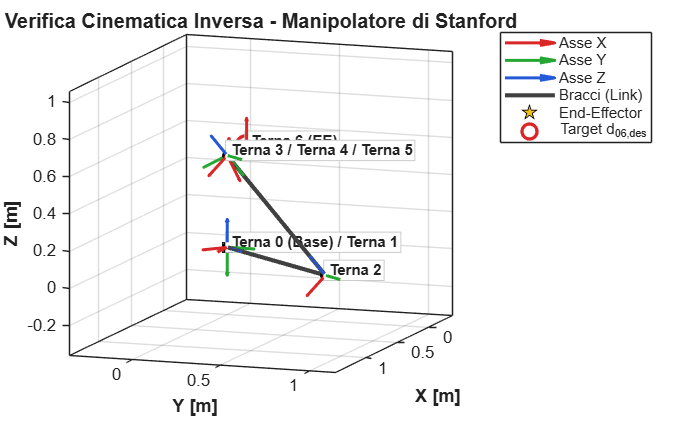

% Costruzione Tabella DH Numerica Completa nella Soluzione IK Calcolata
DH_Table_Num = [q1_sol, 0,      -pi/2, 0;
                q2_sol, d2_num,  pi/2, 0;
                0,      q3_sol,  0,    0;
                q4_sol, 0,      -pi/2, 0;
                q5_sol, 0,       pi/2, 0;
                q6_sol, d6_num,  0,    0];

[T_Num_all, ~] = Compute_DH_Transformations(DH_Table_Num);
T_Num = double(T_Num_all);
n = size(DH_Table_Num, 1);

fig_name    = 'Verifica Cinematica Inversa - Manipolatore di Stanford';
arrow_scale = 0.15;
view_angles = [110, 10];
labels      = {'Terna 0 (Base)', 'Terna 1', 'Terna 2', 'Terna 3', 'Terna 4', 'Terna 5', 'Terna 6 (EE)'};

figure('Name', fig_name, 'Color', 'w');
hold on;
grid on;
box on;
xlabel('X [m]', 'FontWeight', 'bold');
ylabel('Y [m]', 'FontWeight', 'bold');
zlabel('Z [m]', 'FontWeight', 'bold');
view(view_angles(1), view_angles(2));
axis equal;

% 1. Calcolo di Tutte le Posizioni e Orientamenti (Base + n Giunti)
T_cumulative = eye(4);
positions = zeros(n+1, 3);
R_all     = zeros(3, 3, n+1);

positions(1, :) = T_cumulative(1:3, 4).';
R_all(:, :, 1)  = T_cumulative(1:3, 1:3);

for i = 1:n
    T_cumulative = T_cumulative * double(T_Num(:, :, i));
    positions(i+1, :) = T_cumulative(1:3, 4).';
    R_all(:, :, i+1)  = T_cumulative(1:3, 1:3);
end

% 2. Disegno dello Scheletro Meccanico (Bracci)
h_link = plot3(positions(:,1), positions(:,2), positions(:,3), '-', ...
    'Color', [0.25 0.25 0.25], 'LineWidth', 2.5);

% 3. Evidenziazione Giunti Meccanici, End-Effector e Target Desiderato d06_des
col_X = [0.85, 0.15, 0.15];
col_Y = [0.15, 0.65, 0.20];
col_Z = [0.15, 0.35, 0.85];

h_base = plot3(positions(1,1), positions(1,2), positions(1,3), 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', [0.4 0.4 0.4], 'MarkerEdgeColor', 'k');
h_joints = plot3(positions(2:end-1,1), positions(2:end-1,2), positions(2:end-1,3), 'o', ...
    'MarkerSize', 6, 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');
h_ee = plot3(positions(end,1), positions(end,2), positions(end,3), 'p', ...
    'MarkerSize', 10, 'MarkerFaceColor', [0.95 0.75 0.1], 'MarkerEdgeColor', 'k');
h_target = plot3(d06_des(1), d06_des(2), d06_des(3), 'o', ...
    'MarkerSize', 13, 'MarkerEdgeColor', col_X, 'LineWidth', 2.0);

% 4. Disegno delle Terne di Riferimento DH (X=Rosso, Y=Verde, Z=Blu)
h_axes = gobjects(1, 3);
for i = 1:(n+1)
    p = positions(i, :);
    R = R_all(:, :, i);

    qx = quiver3(p(1), p(2), p(3), R(1,1)*arrow_scale, R(2,1)*arrow_scale, R(3,1)*arrow_scale, 0, ...
        'Color', col_X, 'LineWidth', 1.8, 'MaxHeadSize', 0.35);
    qy = quiver3(p(1), p(2), p(3), R(1,2)*arrow_scale, R(2,2)*arrow_scale, R(3,2)*arrow_scale, 0, ...
        'Color', col_Y, 'LineWidth', 1.8, 'MaxHeadSize', 0.35);
    qz = quiver3(p(1), p(2), p(3), R(1,3)*arrow_scale, R(2,3)*arrow_scale, R(3,3)*arrow_scale, 0, ...
        'Color', col_Z, 'LineWidth', 1.8, 'MaxHeadSize', 0.35);

    if i == 1
        h_axes(1) = qx;
        h_axes(2) = qy;
        h_axes(3) = qz;
    end
end

% 5. Etichette Intelligenti con Raggruppamento Origini Coincidenti
visited = false(n+1, 1);
for i = 1:(n+1)
    if visited(i)
        continue;
    end
    dists = sqrt(sum((positions - positions(i, :)).^2, 2));
    coincident_idx = find(dists < 1e-4);
    visited(coincident_idx) = true;
    combined_label = strjoin(labels(coincident_idx), ' / ');
    p = positions(i, :);
    text(p(1), p(2), p(3) + 0.18*arrow_scale, sprintf(' %s', combined_label), ...
        'FontSize', 9, 'FontWeight', 'bold', ...
        'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);
end

% 6. Margine di Visualizzazione Attorno al Robot
all_pts = [positions; d06_des.'; positions + arrow_scale; positions - arrow_scale];
min_xyz = min(all_pts, [], 1);
max_xyz = max(all_pts, [], 1);
span = max(max_xyz - min_xyz);
if span == 0, span = 1; end
margin = 0.15 * span;
xlim([min_xyz(1) - margin, max_xyz(1) + margin]);
ylim([min_xyz(2) - margin, max_xyz(2) + margin]);
zlim([min_xyz(3) - margin, max_xyz(3) + margin]);

% 7. Legenda e Titolo
legend([h_axes(1), h_axes(2), h_axes(3), h_link, h_ee, h_target], ...
    {'Asse X', 'Asse Y', 'Asse Z', 'Bracci (Link)', 'End-Effector', 'Target d_{06,des}'}, ...
    'Location', 'bestoutside');
title(fig_name, 'FontSize', 12, 'FontWeight', 'bold');
hold off;